1. Задаем функцию зекала $R\left(x\right)$:

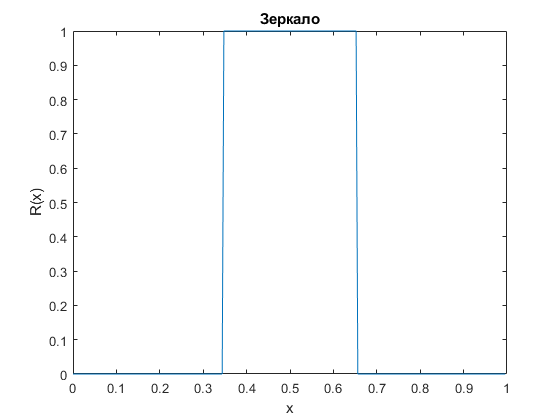

L=1; % длина интервала
N=256; % число точек
dx = L/N; % шаг по x
x=0:L/N:L*((N-1)/N); % вектор {x_j}
xl=0.35*L; % начало зеркала (xr - зекально относительно центра в L/2)
xr=L-xl; % конец зеркала
ixl = round(xl/dx); % индекс левого края зеркала
ixr = N - ixl + 2; % индекс правого края зеркала
R=zeros(N,1); R(1:ixl-1) = 0; R(ixl:ixr) = 1; R(ixr+1:end) = 0; % зеркальце в середине интыервала (N+1 точка)
plot(x,R); title('Зеркало'); xlabel('x'); ylabel('R(x)');

2.  Делаем дискретное синус-преобразование функции зеркала $\textrm{Dst}\left(R\left(x\right)\right)$:

Dst = sintr(R);
k=0:N-1; % номера гармоник

3. Аналитическая формула зависимости значений синус-преобразования зеркала от номера гармоники $\textrm{Fst}\left(R\left(x\right)\right)$:

Fst = [0 2./(k(2:end)*pi).*(cos(k(2:end)*pi*xl/L)-cos(k(2:end)*pi*xr/L))];

4. Сравниваем графики. Аналитическое выражение для гармоник нужно умножить на sqrt(2/N), чтобы оно соответствовало

дискретному аналогу.

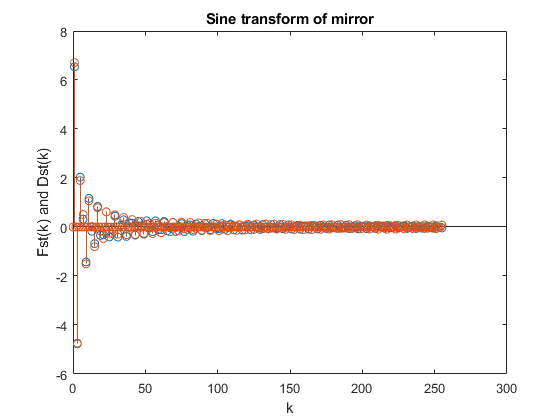

stem(k, Fst/sqrt(2/N))
hold on
stem(k,Dst); title('Sine transform of mirror'); xlabel('k'); ylabel('Fst(k) and Dst(k)');
hold off

5. Обратное преобразование:

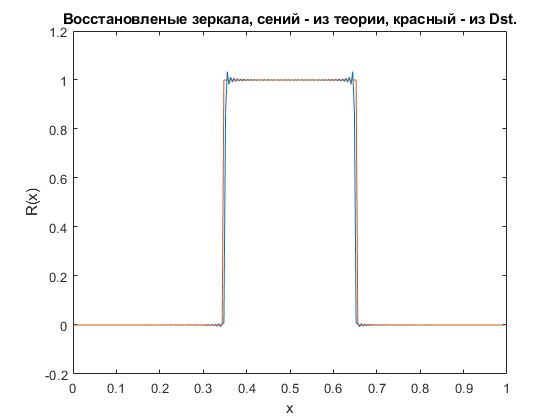

iDst = sintr(Dst);
iFst = sintr(Fst/sqrt(2/N));
plot(x,iFst)
hold on
plot(x,iDst)
hold off
title('Восстановленые зеркала, сений - из теории, красный - из Dst.'); xlabel('x'); ylabel('R(x)');

6. Восстановим зеркало с половинным шагом и с шагом/3, из функции $\textrm{Fst2}$, полученной добавлением N нулей к $\textrm{Fst}$:

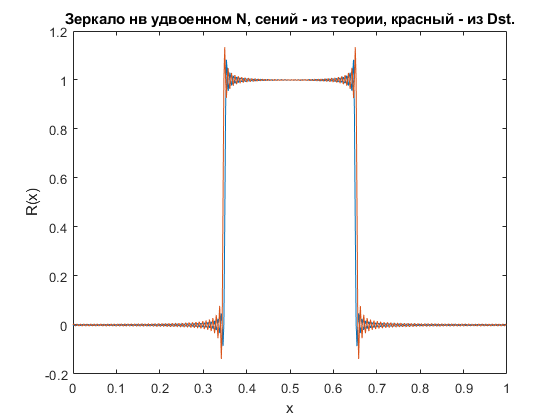

Fst2 = [Fst zeros(1,N)]/sqrt(1/N); % заполняем нулями и умножаем на sqrt(2/(2*N))
iFst2 = sintr(Fst2); % обратное преобразование
iFdst2 = sintr(sqrt(2)*[Dst' zeros(1,N)]);
dx2 = L/N/2; % шаг по x
x2 = 0:dx2:L-dx2;
Fst3 = [Fst zeros(1,2*N)]/sqrt(2/(3*N)); % заполняем нулями и умножаем на sqrt(2/(3*N))
plot(x2,iFst2) % из аналитики (синий)
hold on
plot(x2,iFdst2) % из дискретного преобразования (красный)
hold off
title('Зеркало нв удвоенном N, сений - из теории, красный - из Dst.'); xlabel('x'); ylabel('R(x)');

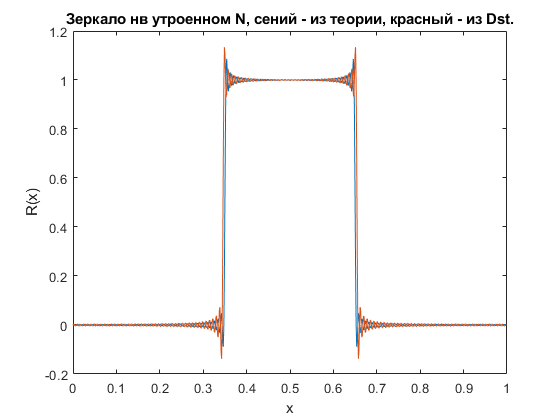

iFst3 = sintr(Fst3); % обратное преобразование
iFdst3 = sintr(sqrt(3)*[Dst' zeros(1,2*N)]);
dx3 = L/N/3;
x3 = 0:dx3:L-dx3;
plot(x3,iFst3) % из аналитики (синий)
hold on
plot(x3,iFdst3) % из дискретного преобразования (красный)
title('Зеркало нв утроенном N, сений - из теории, красный - из Dst.'); xlabel('x'); ylabel('R(x)');
hold off

7. Для сравнения построим матрицу $R_{\textrm{pn}}$:

Rad = zeros(N,N); % матрица полученная дискретно
Rat = zeros(N,N); % матрица полученная из аналитики
j=0:N-1;
% R = 1; xl=0; xr=L; % для теста (сплошное зеркало)
for p=0:N-1
    for n=0:N-1
        Rad(p+1,n+1) = 2/N*sum(R'.*sin(pi*n*j/N).*sin(pi*p*j/N));
        if (n == 0 || p == 0)
            Rat(p+1,n+1) = 0;
        elseif (n == p)
            Rat(p+1,n+1) = (2*n*pi*(-xl + xr) + L*sin((2*n*pi*xl)/L) - L*sin((2*n*pi*xr)/L))/(2.*L*n*pi);
        else
            Rat(p+1,n+1) = ((-sin(((n - p)*pi*xl)/L) + sin(((n - p)*pi*xr)/L))/(n - p) + ...
                (sin(((n + p)*pi*xl)/L) - sin(((n + p)*pi*xr)/L))/(n + p))/pi;
        end
    end
end
% Rad
% Rat
% dr = Rad-Rat;
% mdr=max(max(dr));
% [mr,ir] = max(dr);
% [mc,ic] = max(mr);
% ir(ic)
% ic
% dr(ir(ic),ic)
% dr(ir(ic),ic)-mdr
% 
% rdd = diag(Rad);
% rtd = diag(Rat);
% 
% rdd(end-5:end)
% rtd(end-5:end)
% 
% 
% n = 2; p = 42;
% if (n == 0 || p == 0)
%     rt = 0
% elseif (n == p)
% %     rt = ((L*(sin((2*p*pi*xr)/L) - sin((2*n*pi*xr)/L)))/(p*pi) - 2*xl + 2*xr)/(2.*L)
%     rt = (2*n*pi*(-xl + xr) + L*sin((2*n*pi*xl)/L) - L*sin((2*n*pi*xr)/L))/(2.*L*n*pi)
% else
%     rt = ((-sin(((n - p)*pi*xl)/L) + sin(((n - p)*pi*xr)/L))/(n - p) + ...
%         (sin(((n + p)*pi*xl)/L) - sin(((n + p)*pi*xr)/L))/(n + p))/pi
% end
% rd = 2/N*sum(R'.*sin(pi*n*j/N).*sin(pi*p*j/N))
% 
% Rad(95,51)
% Rat(95,51)

8. Отразим волну с помощю матрицы.

Сначала построим функцию, например гауссову: $u=\mathrm{exp}\left(-\frac{{\left(x-\frac{L}{2}\right)}^2 }{0\ldotp 05}\right)$

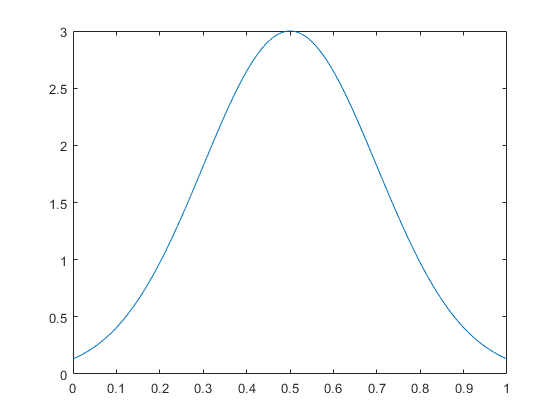

u=3*exp(-(x-L/2).^2/0.08);
plot(x,u)

Сделаем синус-преобразование:

dsu=sintr(u);

и нарисуем его.

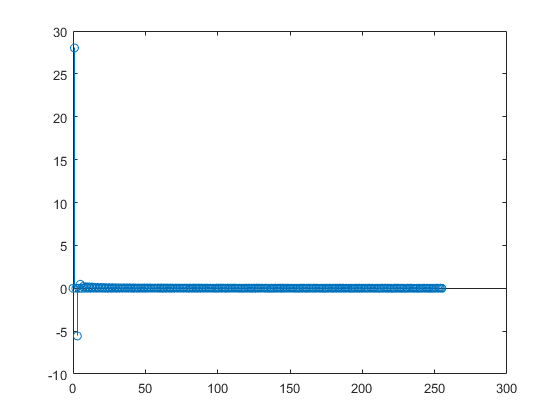

stem(k,dsu)

Обратное преобразование:

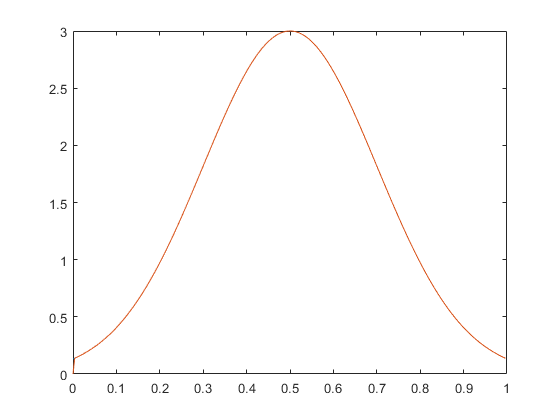

idsu=sintr(dsu);
plot(x,u,x,idsu)

Умножим на мтрицу, и построим то, что получилось:

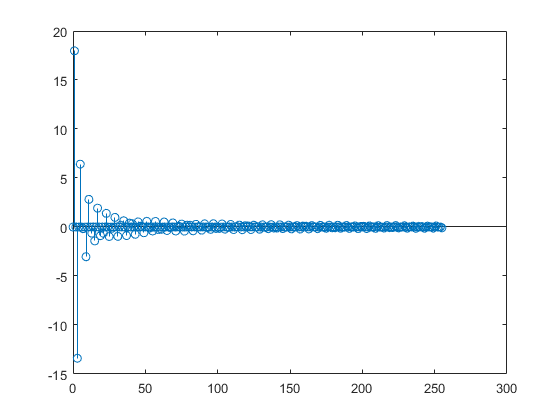

Rdsu=Rat*dsu;
stem(k,Rdsu)

Теперь преобразуем обратно:

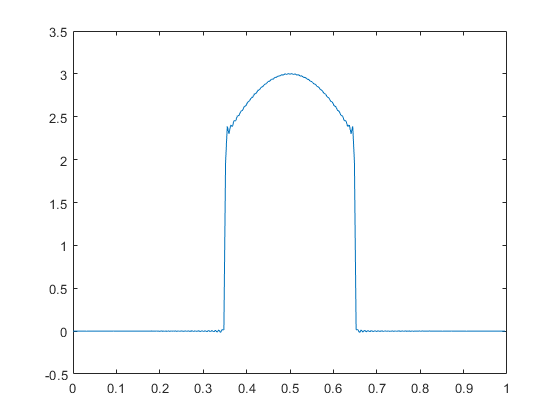

iRdsu=sintr(Rdsu);
plot(x, iRdsu)

 Получим коэффициенты с половиннм шагом:

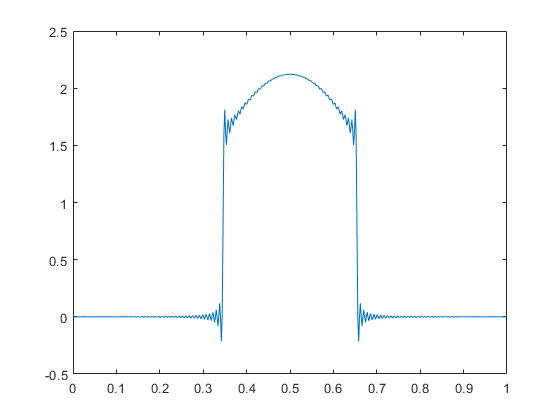

u2 = sintr(sqrt(2)*[dsu' zeros(1,N)]);
Ru2 = u2.*iFdst2/sqrt(2);
plot(x2,Ru2)

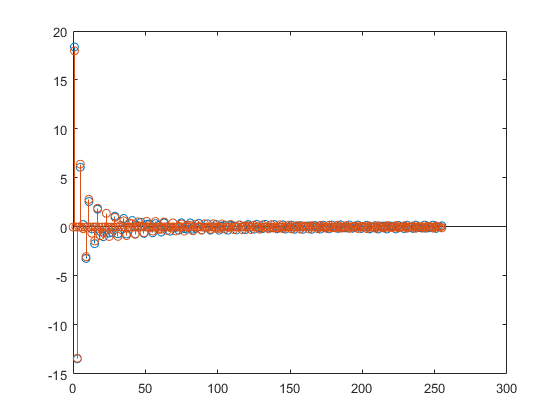

Rdsu2 = sintr(Ru2);
stem(k,Rdsu2(1:N))
hold on
stem(k,Rdsu)
hold off

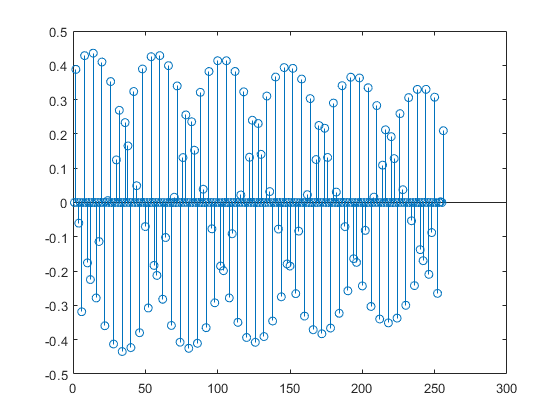

stem(Rdsu2(1:N)-Rdsu)

max(Rdsu2(1:N)-Rdsu)

ans =    0.435459513558970

Посчитаем свертку:

% C = conv(dsu,Fst)
% % stem(k,C(2:N+1))
% % hold on
% % stem(k,Rdsu2(1:N))
% iC=sintr(C(2:N+1))
% stem(iC)